#  QPSK modulation

## QPSK modulation

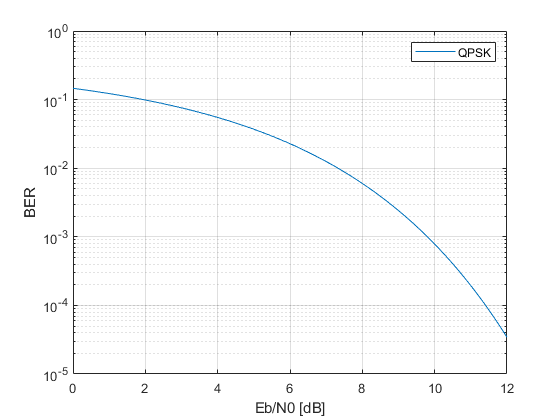

close all;
clear all;
N = 1000;
EbN0_dB = linspace(0,12,N);
EbN0 = 10.^(EbN0_dB/10);
ber = zeros(1,N);

%We assume BER is SER/2
for k=1:N
    a = qfunc(sqrt(EbN0(1,k)));
    ber(1,k)=(2*a-a^2)/2;
end

figure;
semilogy(EbN0_dB,ber);
grid on;
xlabel("Eb/N0 [dB]");
ylabel("BER");
legend("QPSK");

## QPSK and differential QPSK modulation

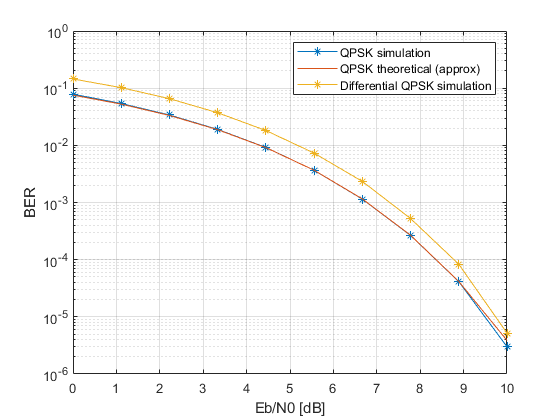

close all;
clear all;
tic;
N = 10;
N_b = 1e7;
fc = 450e6;


EbN0_dB = linspace(0,10,N);
EbN0 = 10.^(EbN0_dB/10);
ber = zeros(1,N);
ber_t = zeros(1,N);
ber_diff = zeros(1,N);

for k=1:N
    a = qfunc(sqrt(2*EbN0(1,k)));
    ber_t(1,k)=(2*a-a^2)/2;
end

rng(0);
for k=1:N
    [~,~,~,ber(1,k)]=simulate_QPSK(EbN0(1,k),N_b,0,0);
end

rng(0);
for k=1:N
    [~,~,~,ber_diff(1,k)]=simulate_QPSK_diff(EbN0(1,k),N_b,0,0);
end

figure;
semilogy(EbN0_dB,ber,'*-');
grid on;
hold on;
semilogy(EbN0_dB,ber_t);
semilogy(EbN0_dB,ber_diff,"*-");
xlabel("Eb/N0 [dB]");
ylabel("BER");
legend("QPSK simulation","QPSK theoretical (approx)","Differential QPSK simulation");

toc;

Elapsed time is 108.247717 seconds.


## QPSK for different phase offsets

clear all;
tic;
N = 10;
N_theo = 1e4;
N_b = 1e8;
dB_min = 0;
dB_max = 11;


EbN0_dB = linspace(dB_min,dB_max,N);
EbN0 = 10.^(EbN0_dB/10);
EbN0_dB_theo = linspace(dB_min,dB_max,N_theo);
EbN0_theo = 10.^(EbN0_dB_theo/10);
ber = zeros(1,N);
ber_t = zeros(1,N);
ber_diff = zeros(1,N);
ber_1 = zeros(1,N);
ber_2 = zeros(1,N);
ber_3 = zeros(1,N);
ber_4 = zeros(1,N);

ser = zeros(1,N);
ser_t = zeros(1,N);
ser_diff = zeros(1,N);
ser_1 = zeros(1,N);
ser_2 = zeros(1,N);
ser_3 = zeros(1,N);
ser_4 = zeros(1,N);


tic
for k=1:N_theo
    a = qfunc(sqrt(2*EbN0_theo(1,k)));
    ber_t(1,k)=(2*a-a^2)/2;
    ser_t(1,k)=(2*a-a^2);
end


rng(0);
for k=1:N
    [~,~,ser(1,k),ber(1,k)]=simulate_QPSK(EbN0(1,k),N_b,0,0);
end


rng(0);
for k=1:N
    [~,~,ser_diff(1,k),ber_diff(1,k)]=simulate_QPSK_diff(EbN0(1,k),N_b,0,0);
end
ber_diff_theo = 2*ber_t;

rng(0);
f_offset = 0;
p_offset = deg2rad(2);
for k=1:N
    [~,~,ser_1(1,k),ber_1(1,k)]=simulate_QPSK(EbN0(1,k),N_b,p_offset,f_offset);
end
ber_1_theo = qpsk_theoretical_ber(EbN0_theo,p_offset);
ser_1_theo = 2*ber_1_theo;

rng(0);
f_offset = 0;
p_offset = deg2rad(5);
for k=1:N
    [~,~,ser_2(1,k),ber_2(1,k)]=simulate_QPSK(EbN0(1,k),N_b,p_offset,f_offset);
end
ber_2_theo = qpsk_theoretical_ber(EbN0_theo,p_offset);
ser_2_theo = 2*ber_2_theo;

rng(0);
f_offset = 0;
p_offset = deg2rad(10);
for k=1:N
    [~,~,ser_3(1,k),ber_3(1,k)]=simulate_QPSK(EbN0(1,k),N_b,p_offset,f_offset);
end
ber_3_theo = qpsk_theoretical_ber(EbN0_theo,p_offset);
ser_3_theo = 2*ber_3_theo;

rng(0);
f_offset = 0;
p_offset = deg2rad(20);
for k=1:N
    [~,~,ser_3(1,k),ber_4(1,k)]=simulate_QPSK(EbN0(1,k),N_b,p_offset,f_offset);
end
ber_4_theo = qpsk_theoretical_ber(EbN0_theo,p_offset);
ser_4_theo = 2*ber_4_theo;

toc

Elapsed time is 2668.321255 seconds.


save('qpsk_mod_simulation_1.mat');

Execute to plot

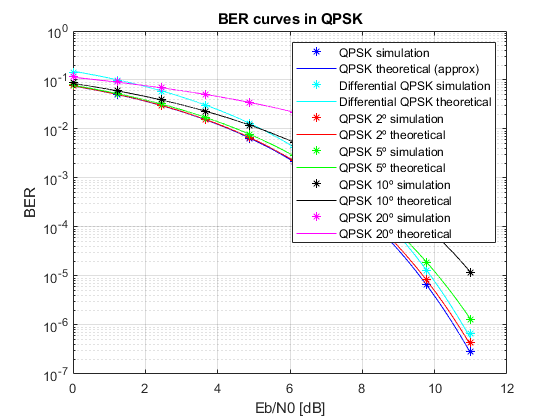

load('qpsk_mod_simulation_1.mat')
close all; 
figure;
semilogy(EbN0_dB,ber,'*b');
grid on;
hold on;
semilogy(EbN0_dB_theo,ber_t,"b");
semilogy(EbN0_dB,ber_diff,"*c");
semilogy(EbN0_dB_theo,ber_diff_theo,"c");
semilogy(EbN0_dB,ber_1,"*r");
semilogy(EbN0_dB_theo,ber_1_theo,"r");
semilogy(EbN0_dB,ber_2,"*g");
semilogy(EbN0_dB_theo,ber_2_theo,"g");
semilogy(EbN0_dB,ber_3,"*k");
semilogy(EbN0_dB_theo,ber_3_theo,"k");
semilogy(EbN0_dB,ber_4,"*m");
semilogy(EbN0_dB_theo,ber_4_theo,"m");
xlabel("Eb/N0 [dB]");
ylabel("BER");
legend("QPSK simulation",...
       "QPSK theoretical (approx)",...
       "Differential QPSK simulation",...
       "Differential QPSK theoretical",...
       "QPSK 2º simulation",...
       "QPSK 2º theoretical",...
       "QPSK 5º simulation",...
       "QPSK 5º theoretical",...
       "QPSK 10º simulation",...
       "QPSK 10º theoretical",...
       "QPSK 20º simulation",...
       "QPSK 20º theoretical");
title("BER curves in QPSK")

## QPSK for different random gaussian phase offsets

clear all;
tic;
N = 10;
N_theo = 1e4;
N_b = 1e8;
dB_min = 0;
dB_max = 11;


EbN0_dB = linspace(dB_min,dB_max,N);
EbN0 = 10.^(EbN0_dB/10);
EbN0_dB_theo = linspace(dB_min,dB_max,N_theo);
EbN0_theo = 10.^(EbN0_dB_theo/10);

ber_t = zeros(1,N);
ber_0 = zeros(1,N);
ber_1 = zeros(1,N);
ber_2 = zeros(1,N);
ber_3 = zeros(1,N);
ber_4 = zeros(1,N);

ser_t = zeros(1,N);
ser_0 = zeros(1,N);
ser_1 = zeros(1,N);
ser_2 = zeros(1,N);
ser_3 = zeros(1,N);
ser_4 = zeros(1,N);


tic
for k=1:N_theo
    a = qfunc(sqrt(2*EbN0_theo(1,k)));
    ber_t(1,k)=(2*a-a^2)/2;
    ser_t(1,k)=(2*a-a^2);
end


ber_diff_theo = ber_t*2;


rng(0);
p_mean = 0;
p_std = deg2rad(2);
for k=1:N
    [~,~,ser_0(1,k),ber_0(1,k)]=simulate_QPSK_rp(EbN0(1,k),N_b,p_mean,p_std);
end
ber_0_theo = qpsk_theoretical_ber_rp(EbN0_theo,p_mean,p_std);

rng(0);
p_mean = 0;
p_std = deg2rad(5);
for k=1:N
    [~,~,ser_1(1,k),ber_1(1,k)]=simulate_QPSK_rp(EbN0(1,k),N_b,p_mean,p_std);
end
ber_1_theo = qpsk_theoretical_ber_rp(EbN0_theo,p_mean,p_std);

rng(0);
p_mean = deg2rad(0);
p_std = deg2rad(10);
for k=1:N
    [~,~,ser_2(1,k),ber_2(1,k)]=simulate_QPSK_rp(EbN0(1,k),N_b,p_mean,p_std);
end
ber_2_theo = qpsk_theoretical_ber_rp(EbN0_theo,p_mean,p_std);


rng(0);
p_mean = deg2rad(2);
p_std = deg2rad(5);
for k=1:N
    [~,~,ser_3(1,k),ber_3(1,k)]=simulate_QPSK_rp(EbN0(1,k),N_b,p_mean,p_std);
end
ber_3_theo = qpsk_theoretical_ber_rp(EbN0_theo,p_mean,p_std);


rng(0);
p_mean = deg2rad(5);
p_std = deg2rad(5);
for k=1:N
    [~,~,ser_4(1,k),ber_4(1,k)]=simulate_QPSK_rp(EbN0(1,k),N_b,p_mean,p_std);
end
ber_4_theo = qpsk_theoretical_ber_rp(EbN0_theo,p_mean,p_std);


toc

Elapsed time is 2152.846490 seconds.


save('qpsk_mod_simulation_2.mat');


Execute to plot

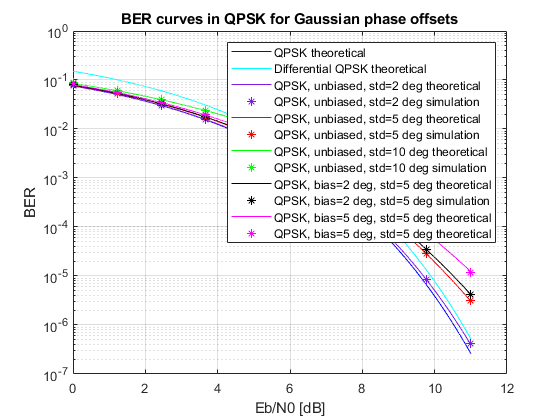

load('qpsk_mod_simulation_2.mat')
close all; 
figure;
semilogy(EbN0_dB_theo,ber_t,"b");
grid on;
hold on;
semilogy(EbN0_dB_theo,ber_diff_theo,"c");
semilogy(EbN0_dB_theo,ber_0_theo,'Color',[0.5 0.1 0.9]);
semilogy(EbN0_dB,ber_0,"*",'Color',[0.5 0.1 0.9]);
semilogy(EbN0_dB_theo,ber_1_theo,"r");
semilogy(EbN0_dB,ber_1,"*r");
semilogy(EbN0_dB_theo,ber_2_theo,"g");
semilogy(EbN0_dB,ber_2,"*g");
semilogy(EbN0_dB_theo,ber_3_theo,"k");
semilogy(EbN0_dB,ber_3,"*k");
semilogy(EbN0_dB_theo,ber_4_theo,"m");
semilogy(EbN0_dB,ber_4,"*m");
xlabel("Eb/N0 [dB]");
ylabel("BER");
legend("QPSK theoretical",...
       "Differential QPSK theoretical",...
       "QPSK, unbiased, std=2 deg theoretical",...
       "QPSK, unbiased, std=2 deg simulation",...
       "QPSK, unbiased, std=5 deg theoretical",...
       "QPSK, unbiased, std=5 deg simulation",...
       "QPSK, unbiased, std=10 deg theoretical",...
       "QPSK, unbiased, std=10 deg simulation",...
       "QPSK, bias=2 deg, std=5 deg theoretical",...
       "QPSK, bias=2 deg, std=5 deg simulation",...
       "QPSK, bias=5 deg, std=5 deg theoretical",...
       "QPSK, bias=5 deg, std=5 deg theoretical");
title("BER curves in QPSK for Gaussian phase offsets");

## QPSK for different frequency offsets (asymptotic behaviour)

clear all;
tic;
N = 10;
N_theo = 1e4;
N_b = 1e6;
dB_min = 0;
dB_max = 11;


EbN0_dB = linspace(dB_min,dB_max,N);
EbN0 = 10.^(EbN0_dB/10);
EbN0_dB_theo = linspace(dB_min,dB_max,N_theo);
EbN0_theo = 10.^(EbN0_dB_theo/10);

ber_t = zeros(1,N);
ber_0 = zeros(1,N);
ber_1 = zeros(1,N);
ber_2 = zeros(1,N);
ber_3 = zeros(1,N);
ber_4 = zeros(1,N);

ser_t = zeros(1,N);
ser_0 = zeros(1,N);
ser_1 = zeros(1,N);
ser_2 = zeros(1,N);
ser_3 = zeros(1,N);
ser_4 = zeros(1,N);


tic
for k=1:N_theo
    a = qfunc(sqrt(2*EbN0_theo(1,k)));
    ber_t(1,k)=(2*a-a^2)/2;
    ser_t(1,k)=(2*a-a^2);
end


ber_diff_theo = ber_t*2;

rng(0);
f_offset = 1e-5;
p_offset = 0;
for k=1:N
    [~,~,ser_0(1,k),ber_0(1,k)]=simulate_QPSK(EbN0(1,k),N_b,p_offset,f_offset);
end

rng(0);
f_offset = 1e-5;
p_offset = 0;
for k=1:N
    [~,~,ser_1(1,k),ber_1(1,k)]=simulate_QPSK_diff(EbN0(1,k),N_b,p_offset,f_offset);
end

rng(0);
f_offset = 2e-5;
p_offset = 0;
for k=1:N
    [~,~,ser_2(1,k),ber_2(1,k)]=simulate_QPSK_diff(EbN0(1,k),N_b,p_offset,f_offset);
end


rng(0);
f_offset = 1e-4;
p_offset = 0;
for k=1:N
    [~,~,ser_3(1,k),ber_3(1,k)]=simulate_QPSK_diff(EbN0(1,k),N_b,p_offset,f_offset);
end


rng(0);
f_offset = 1e-3;
p_offset = 0;
for k=1:N
    [~,~,ser_4(1,k),ber_4(1,k)]=simulate_QPSK_diff(EbN0(1,k),N_b,p_offset,f_offset);
end


toc

Elapsed time is 35.272321 seconds.


save('qpsk_mod_simulation_3.mat');

Execute to plot

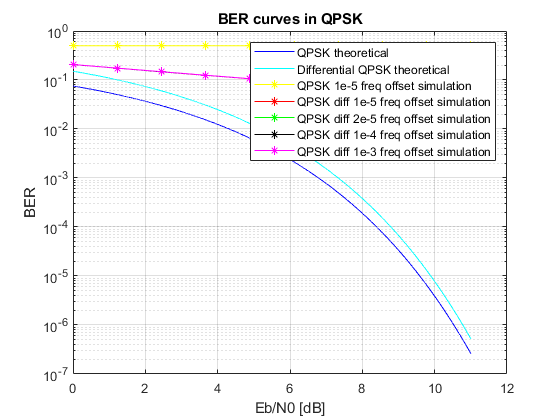

load('qpsk_mod_simulation_3.mat')
close all; 
figure;
semilogy(EbN0_dB_theo,ber_t,"b");
grid on;
hold on;
semilogy(EbN0_dB_theo,ber_diff_theo,"c");
semilogy(EbN0_dB,ber_0,"*-y");
semilogy(EbN0_dB,ber_1,"*-r");
semilogy(EbN0_dB,ber_2,"*-g");
semilogy(EbN0_dB,ber_3,"*-k");
semilogy(EbN0_dB,ber_4,"*-m");
xlabel("Eb/N0 [dB]");
ylabel("BER");
legend("QPSK theoretical",...
       "Differential QPSK theoretical",...
       "QPSK 1e-5 freq offset simulation",...
       "QPSK diff 1e-5 freq offset simulation",...
       "QPSK diff 2e-5 freq offset simulation",...
       "QPSK diff 1e-4 freq offset simulation",...
       "QPSK diff 1e-3 freq offset simulation");
title("BER curves in QPSK");

## Conclusión

Se pueden ver las gráficas de error para distintos errores fijos en la fase. 

El caracter cicloestacionario que tiene la señal cuando queda algún error en la frecuencia, hace que sea mejor poner cotas superiores que sean fáciles de calcular analíticamente que intentar encontrar resultados exactos.

Hay que tener cuidado, al estimar parametros de un modelo cicloestacionario, puede ser mejor simular menos puntos pero que representen periodos completos que muchos puntos que se dejen un periodo a medias.